# LAB 2: FREQUENCY DOMAIN AND TRANSFER FUNCTIONS

%---------------------------------------
% Fill in your group number.
GroupNumber = 50;
% Fill in your student Name and ID.
Students(1).Name = '';
Students(1).ID = '';
Students(2).Name = 'Eric Macpherson';
Students(2).ID = '261151403';
%---------------------------------------

## **0. Objectives**

The purpose of this lab is to overview the basic `MATLAB` functions in linear systems and control. At the end of this lab, you will be able to plot the step and impulse response of a rational transfer function and analyze with first and second order transfer functions.

## **1. Introduction**

The first step in the design of a control system is to identify a mathematical model of the system. Such a mathematical model could be derived either from physical laws or from experimental data. For Linear Time Invariant (LTI) systems, we only need to identify the impulse response or it's frequency-domain representation: the transfer function.

In this lab, we introduce how to model transfer functions in `MATLAB`. There are various methods to define a transfer function in `MATLAB`. As an example, suppose we have a system described by the following constant coefficient linear differential equation:


$$ a_2 \displaystyle \frac{d^2 y(t)}{dt} + a_1 \displaystyle \frac{d
y(t)}{dt} + a_0 y(t) = b_1 \displaystyle \frac{d u(t)}{dt} + b_0 u(t) $$


We know that the transfer function of this system is


$$ H(s) = \displaystyle \frac{Y(s)}{U(s)} = \displaystyle \frac{b_1 s +
b_0}{a_2 s^2 + a_1 s + a_0} $$


Suppose $a_0=2$, $a_1=3$, $a_2=1$, $a_3=1$, $b_0=2$, $b_1=2$.

The first method of specifying the function is to literally type out this expression. We first define the symbol $s$ using the `tf` function and then define the transfer function $H$ in terms of $s$. For example:

% Assign values to the coefficients
a2 = 1;
a1 = 3;
a0 = 2;
b1 = 2;
b0 = 6;
% Define s symbolically in frequency domain
s = tf('s');

Then we can directly define the transfer function as follows.

H1 = (b1 * s + b0) / (a2 * s^2 + a1 * s + a0)

H1 =
 
     2 s + 6
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


The second method is to directly specify the polynomials of the numerator and the denominators.

% Define the numerator
num = [b1, b0];
% Define the denominator
den = [a2, a1, a0];
% Define the transfer function
H2 = tf(num, den)

H2 =
 
     2 s + 6
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


Another way to define the transfer function is to use the gain, poles and zeros. Let's reconsider the above transfer function in pole-zero form.


$$ H(s) = 2 \displaystyle \frac{s+2}{(s+1)(s+2)} $$


We can specify the transfer function in the pole zero form using the following code.

k = 2; % The gain
z = [-3]; % The set of zeros
p = [-1, -2]; % The set of poles
H3 = zpk(z, p, k) % Define the transfer function

H3 =
 
    2 (s+3)
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


There are other forms of using the `zpk` function. Use `doc zpk` for more information.

It is possible to identify the poles and zeros of a **rational** transfer function using `tf2zp`:

[z, p, k] = tf2zp(num, den)

z = -3

p =     -2
    -1


k = 2

## **2. Plotting Impulse and Step Responses**

To plot the impulse response of a transfer function, one can use `impulse(sys)`. To plot the step response, one can use `step(sys)`. As an example, we plot the impulse and step responses of the system defined in the previous section:

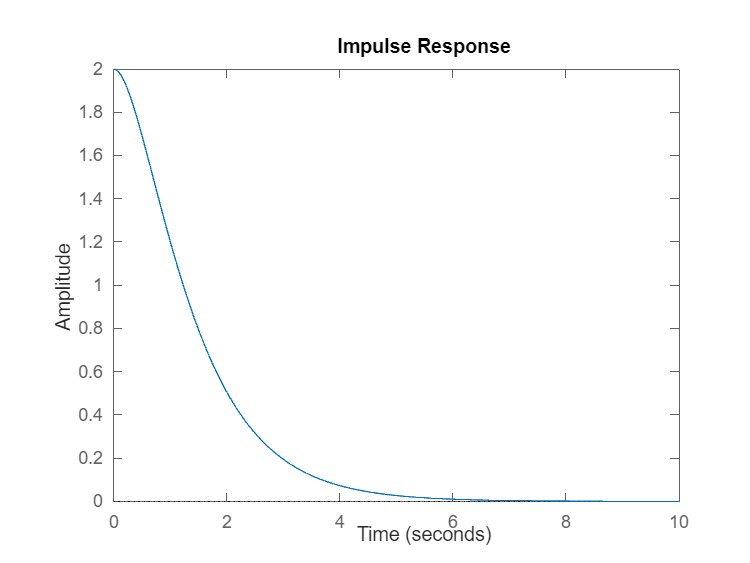

T = 10; % Final time value
figure;
impulse(H1, T)

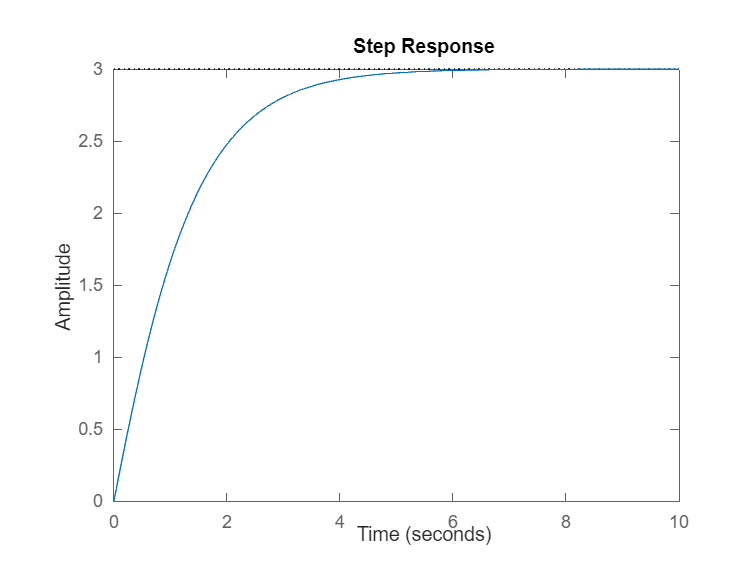

figure;
step(H1, T)

To find the poles and zeros of a transfer function, use `pole(system)` and `zero(systems)`. To plot the pole-zero plot, use `pzplot(system)`. For example, for the system defined above, the poles are

pole(H1)

ans =     -2
    -1


and the zeros are

zero(H1)

ans = -3

We can show the pole-zero plot using

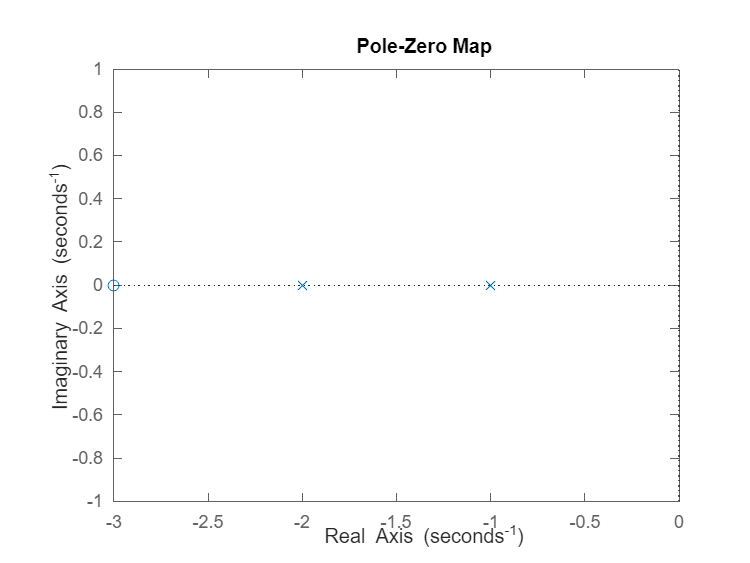

pzplot(H1)

## **Interconnecting systems**

To get the transfer function for two systems connected in feedback, use

H = feedback(H1, H2) % Feedback or closed-loop interconnection of systems

H =
 
     2 s^3 + 12 s^2 + 22 s + 12
  --------------------------------
  s^4 + 6 s^3 + 17 s^2 + 36 s + 40
 
Continuous-time transfer function.
Model Properties


Use `doc feedback` for more information.

## **3. System Response characteristics**

Consider the following step response of an unknown transfer function.

<<fig_lab02_secondorder.png>>

Depending on the location of the zeros and poles in a transfer function, it is possible to define a system response by the following characteristics:

- Rise time ($t_r$): is the time it takes the system to reach to rise from 10% to 90% of its final value.

- Peak time ($t_p$): is the time until the response hits its maximum overshoot.

- Overshoot ($M_p$): is the peak value of the step response of the system.

- Settling time ($t_s$): is the time for the response to settle within $\pm \Delta$ % of its final value.

It is possible to find these values in `MATLAB` given a transfer function. `stepinfo(sys)` computes the step-response characteristics for a dynamic system model. For example

stepinfo(H1)

ans = struct with fields:
         RiseTime: 2.4200
    TransientTime: 4.1960
     SettlingTime: 4.1960
      SettlingMin: 2.7023
      SettlingMax: 2.9974
        Overshoot: 0
       Undershoot: 0
             Peak: 2.9974
         PeakTime: 7.3222


## *Question 1 (2 marks)*

For $\xi = \{0.25, 0.75, 1, 2\}$, plot the step response **(for 25 sec)** and identify the characteristics of the transient response of the following system


$$ G(s) = \displaystyle \frac{1}{s^2+2 \xi s + 1} $$


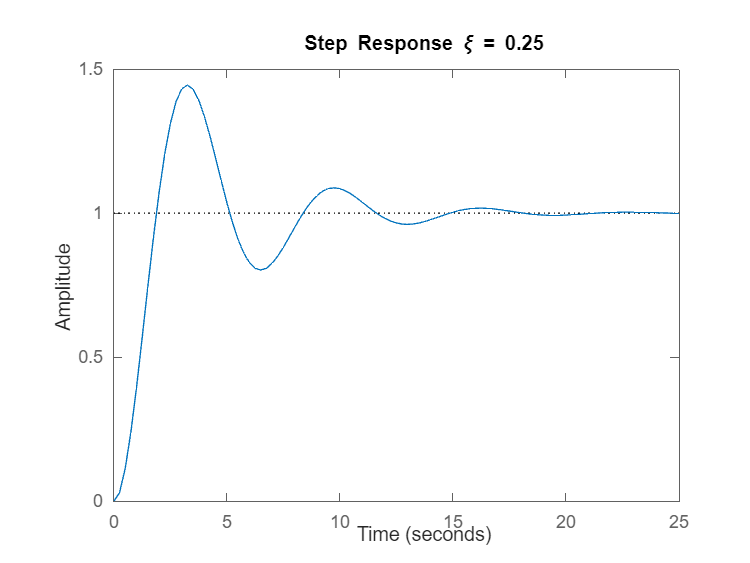

% For xi = 0.25
%
final_T = 25;
H5 = tf([0, 1],[1, 0.5, 1]);
figure;
step(H5, final_T)
title("Step Response \xi = 0.25")

stepinfo(H5)

ans = struct with fields:
         RiseTime: 1.2687
    TransientTime: 14.1159
     SettlingTime: 14.1159
      SettlingMin: 0.8027
      SettlingMax: 1.4432
        Overshoot: 44.3235
       Undershoot: 0
             Peak: 1.4432
         PeakTime: 3.3157


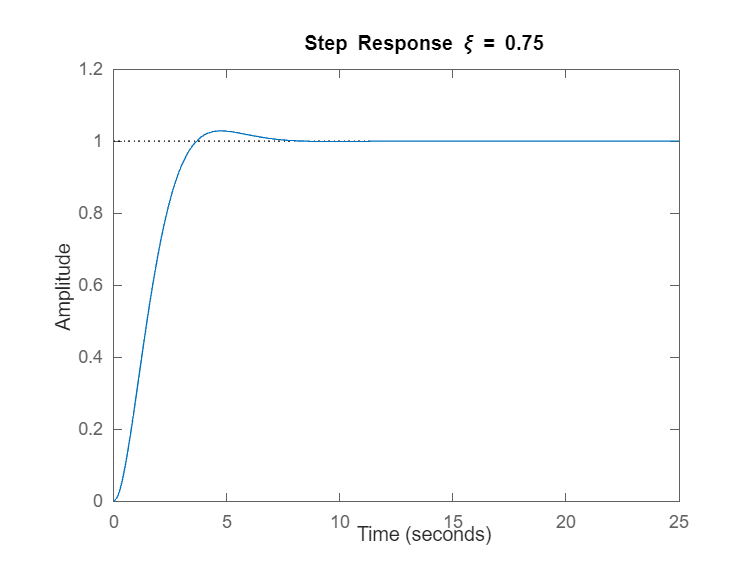

% For xi = 0.75

H6 = tf([0, 1],[1, 1.5, 1]);
figure;
step(H6, final_T)
title("Step Response \xi = 0.75")

stepinfo(H6)

ans = struct with fields:
         RiseTime: 2.2884
    TransientTime: 5.7426
     SettlingTime: 5.7426
      SettlingMin: 0.9049
      SettlingMax: 1.0284
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 1.0284
         PeakTime: 4.7280


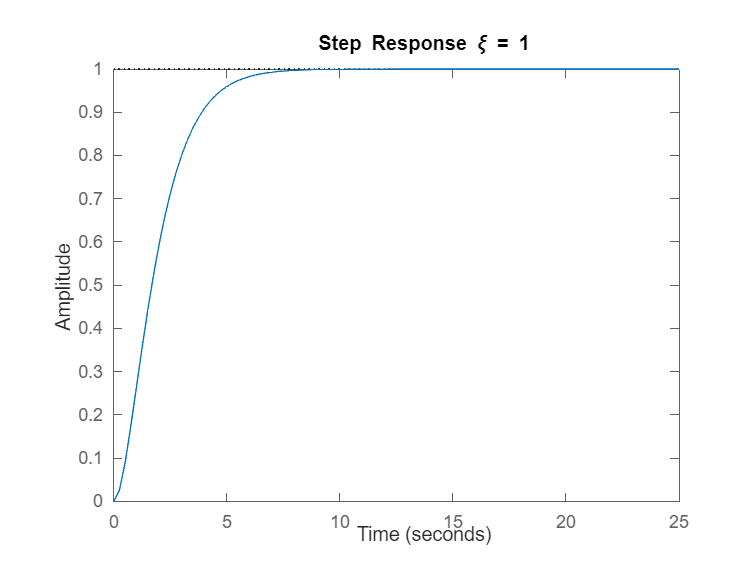

% For xi = 1
%
H7 = tf([0, 1],[1, 2, 1]);
figure;
step(H7, final_T)
title("Step Response \xi = 1")

stepinfo(H7)

ans = struct with fields:
         RiseTime: 3.3579
    TransientTime: 5.8339
     SettlingTime: 5.8339
      SettlingMin: 0.9000
      SettlingMax: 0.9994
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9994
         PeakTime: 9.7900


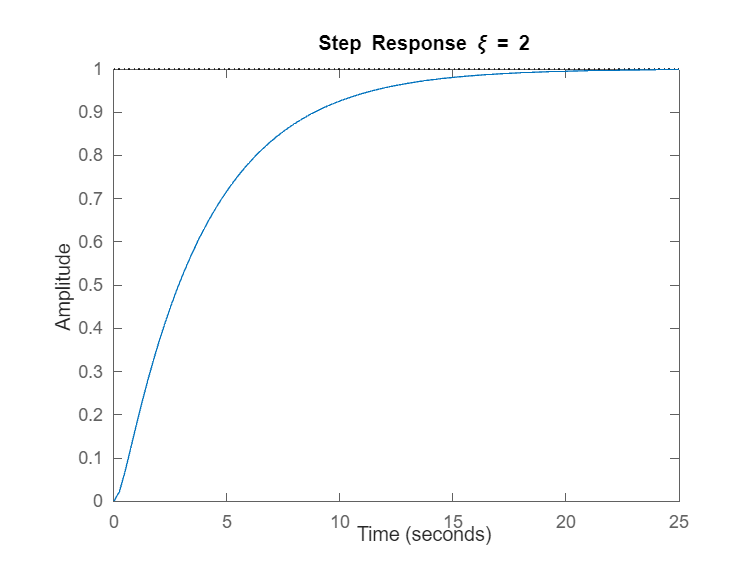

% For xi = 2

H8 = tf([0, 1],[1, 4, 1]);
figure;
step(H8, final_T)
title("Step Response \xi = 2")

stepinfo(H8)

ans = struct with fields:
         RiseTime: 8.2308
    TransientTime: 14.8789
     SettlingTime: 14.8789
      SettlingMin: 0.9017
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 27.3269


## *Question 2 (4 marks)*

Consider the following open-loop unstable system.


$$ Q(s) = \displaystyle \frac{s+1}{s(s-1)(s+6)} $$


A constant gain $k$ (controller) is used to stabilize this system. For different values of $k \in \{10,\ 20,\ 50,\ 100\}$, plot the step response **(for 15 seconds)** of the closed-loop system and identify its characteristics using `stepinfo`.

<<fig_lab02_closedLoop.png>>

% Define the transfer function
%
Q = tf([0, 1, 1], [1, 5, -6, 0])

Q =
 
        s + 1
  -----------------
  s^3 + 5 s^2 - 6 s
 
Continuous-time transfer function.
Model Properties


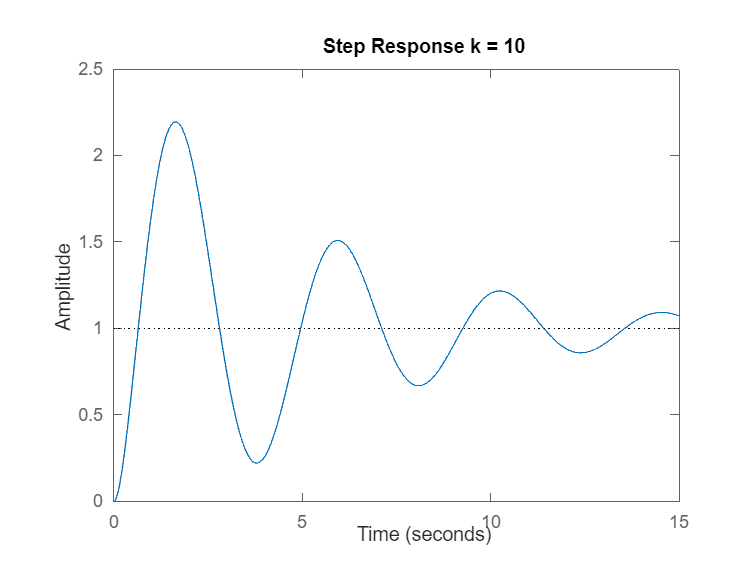

% k = 10
%
k = 10;
T = 15;
figure;
step(feedback(Q*k, 1), T)
title("Step Response k = 10");

stepinfo(feedback(Q*k, 1))

ans = struct with fields:
         RiseTime: 0.4424
    TransientTime: 21.2506
     SettlingTime: 21.4690
      SettlingMin: 0.2212
      SettlingMax: 2.1939
        Overshoot: 119.3930
       Undershoot: 0
             Peak: 2.1939
         PeakTime: 1.6408


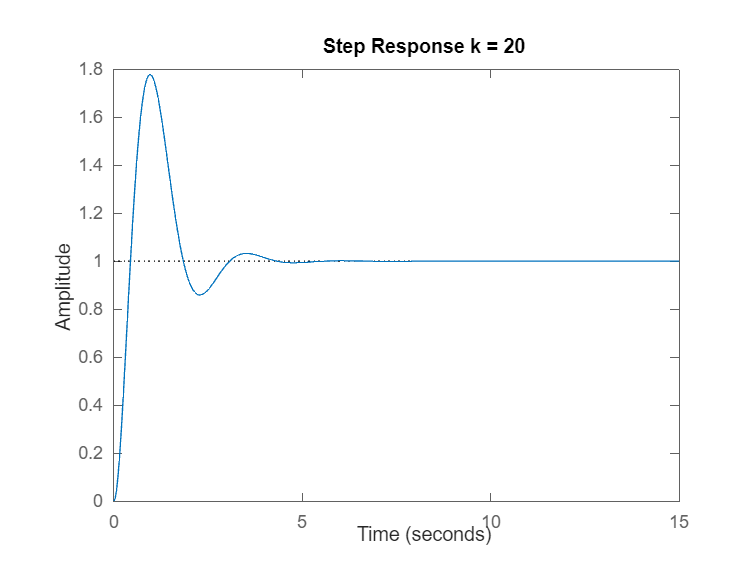

% k = 20
%
k = 20;
figure;
step(feedback(Q*k, 1), T)
title("Step Response k = 20");

stepinfo(feedback(Q*k, 1))

ans = struct with fields:
         RiseTime: 0.2989
    TransientTime: 3.8974
     SettlingTime: 3.8974
      SettlingMin: 0.8592
      SettlingMax: 1.7772
        Overshoot: 77.7158
       Undershoot: 0
             Peak: 1.7772
         PeakTime: 0.9644


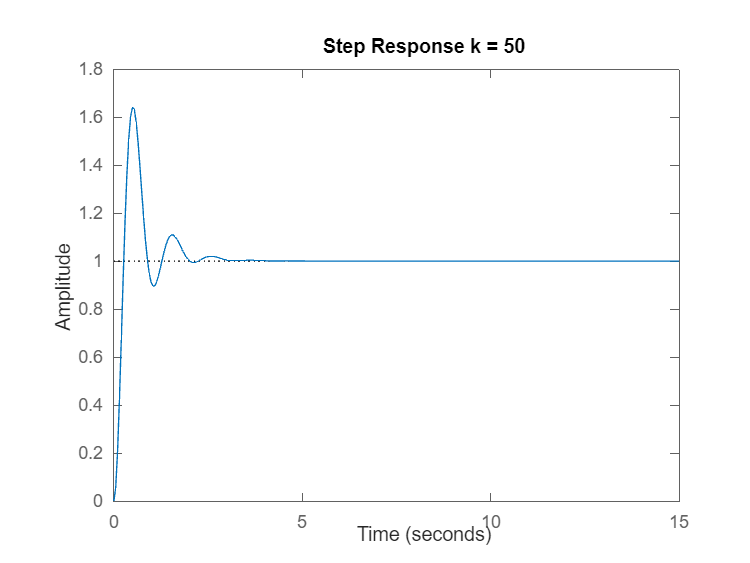

% k = 50
%
k = 50;
figure;
step(feedback(Q*k, 1), T)
title("Step Response k = 50");

stepinfo(feedback(Q*k, 1))

ans = struct with fields:
         RiseTime: 0.1767
    TransientTime: 2.6377
     SettlingTime: 2.6377
      SettlingMin: 0.8948
      SettlingMax: 1.6430
        Overshoot: 64.3033
       Undershoot: 0
             Peak: 1.6430
         PeakTime: 0.5062


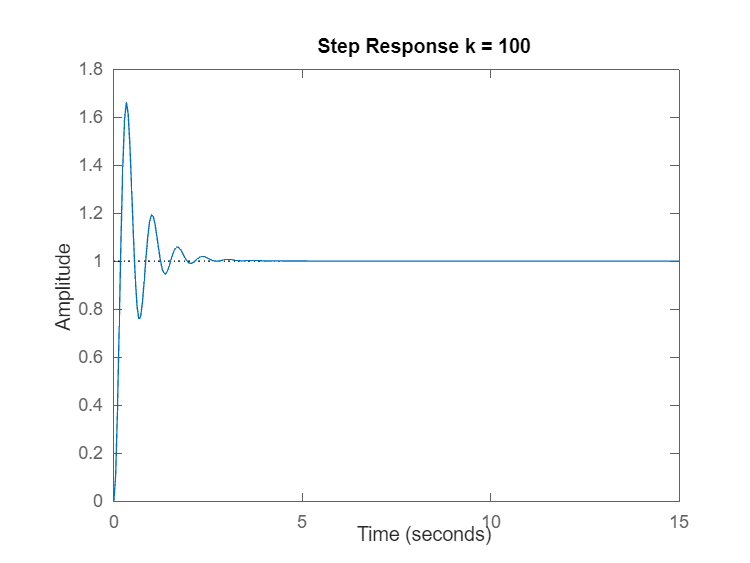

% k = 100
%
k = 100;
figure;
step(feedback(Q*k, 1), T)
title("Step Response k = 100")

stepinfo(feedback(Q*k, 1))

ans = struct with fields:
         RiseTime: 0.1190
    TransientTime: 1.8674
     SettlingTime: 1.8674
      SettlingMin: 0.7606
      SettlingMax: 1.6607
        Overshoot: 66.0662
       Undershoot: 0
             Peak: 1.6607
         PeakTime: 0.3303


## *Question 3 (4 marks)*

Consider the closed-loop transfer function in Question 2.


$$ T(s) = \displaystyle \frac{k Q(s)}{1 + k Q(s)} $$


We would like to approximate this system to a second order system of the form:


$$ G(s) = \displaystyle
\frac{\displaystyle\frac{k}{|p_3|}(s-z_1)}{(s-p_1)(s-p_2)} $$


- For $k = \{10,\ 20\}$, find $p_1$, $p_2$ and $p_3$, where $p_1$ and $p_2$ are the dominant poles (i.e., poles with the smallest absolute real values) and $p_3$ is the ineffective pole(i.e., the pole with the largest absolute real value).

- For $k = \{10,\ 20\}$, plot the step response of the new second order system for **15 sec** and identify its characteristics using `stepinfo`.

- For $k = \{10,\ 20\}$, compare the step response with those obtained in Question 2. What do you observe?

- 1)

% Find the poles of the two transfer functions
%

HFeedback = (feedback(k*Q, 1));
Q_Poles = pole(Q)

Q_Poles =      0
    -6
     1


Feedback_poles = pole(feedback(k*Q, 1))

Feedback_poles =   -1.9424 + 9.2679i
  -1.9424 - 9.2679i
  -1.1152 + 0.0000i





Z = zero(feedback(k*Q, 1))

Z = -1

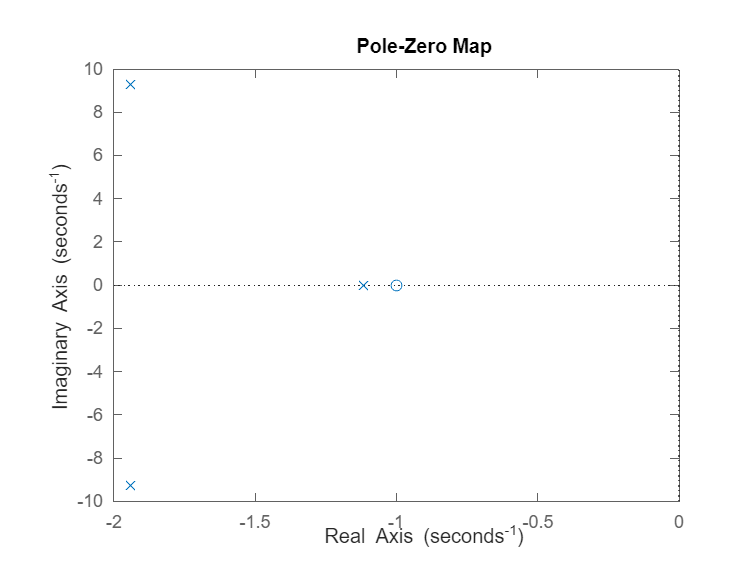

pzplot(feedback(k*Q, 1))



% 



% Transfer functions with dominant poles
%

% not sure what they want here, the poles seem too close to ignore, k is
% still 100 at this point

TF_approximate = zpk(Z, Feedback_poles(1:2, 1), k./Feedback_poles(3,1))

TF_approximate =
 
      -89.668 (s+1)
  ----------------------
  (s^2 + 3.885s + 89.67)
 
Continuous-time zero/pole/gain model.
Model Properties


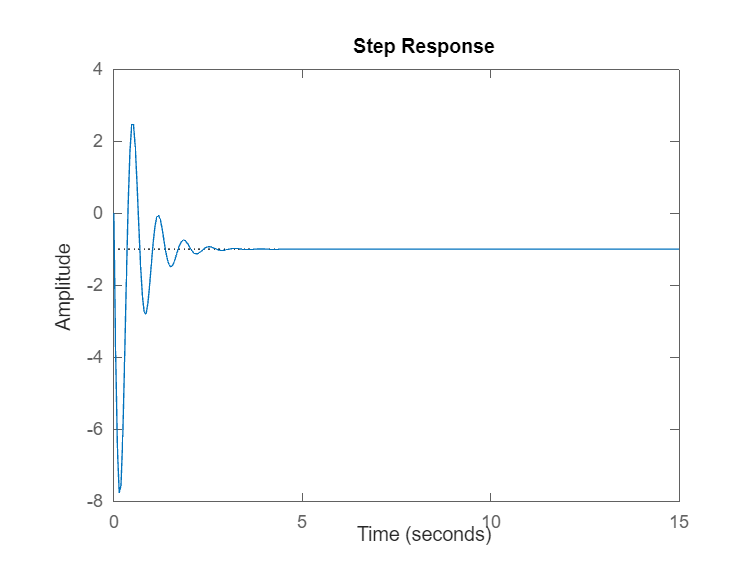

step(TF_approximate, T)

zero(TF_approximate)

ans = -1

pole(TF_approximate)

ans =   -1.9424 + 9.2679i
  -1.9424 - 9.2679i


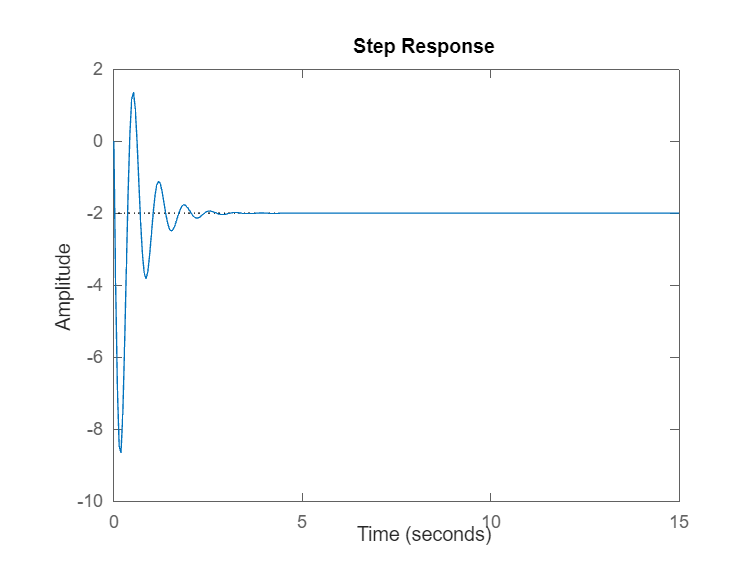

step(TF_approximate-feedback(k*Q, 1), T)

% k = 10
%

% k = 20
%

- 2)

% k = 10
%

% k = 20
%

- 3)

% k = 10
%

% k = 20
%

% [Answer here]